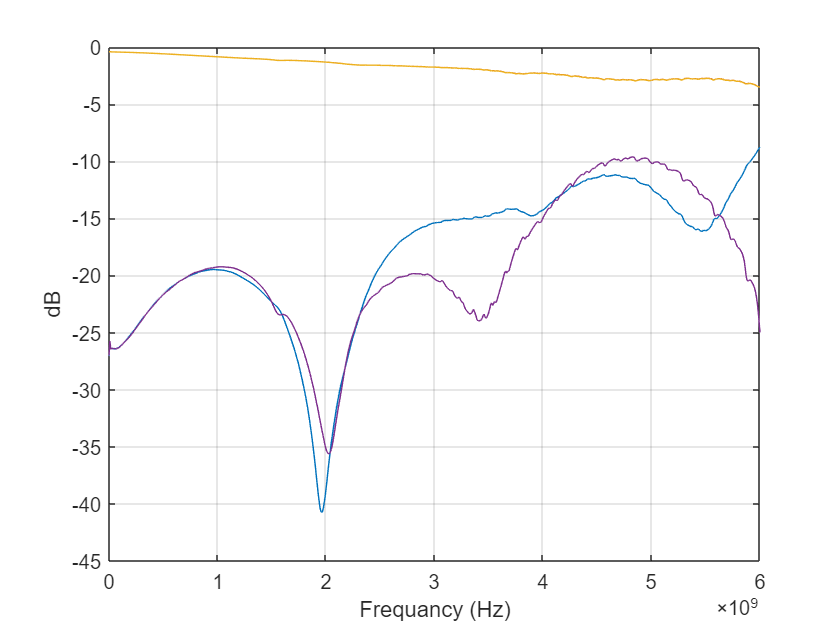

clc;
clear;
[frequancies,M,dB,A,R,I]=read_through_it("rf2_rfc.s2p");   

datatype="dB";
indexoption=false;
if indexoption==0
    rfplot_lite(frequancies,M,dB,A,R,I,datatype)
else
    i=1;
    j=1;
    rfplot_index(i,j,frequancies,M,dB,A,R,I,datatype)
end

%This function reads through the snp file, Sorts the data and returns n*n matrices for each of the
%parameters- Magnitude,dB,Real,Imaginary and Angle

function [frequancies, M, dB, A, R, I]=read_through_it(filename)     

f=fopen(filename,"r");
n_of_snp=fliplr(filename{1});
global n
n=str2double(n_of_snp(2));
a=fscanf(f,'%c');
if contains(a,'noise parameter',"IgnoreCase",true)
    a=extractBefore(a,'Noise');
end
f2=fopen('temporary.snp',"w");
fprintf(f2,a);
fclose('all');
f=fopen('temporary.snp','r');
global c
c=textscan(f,'%s',6,'CommentStyle','!');
d=textscan(f,'%f','CommentStyle','!');
fclose('all');
delete temporary.snp;
i=1;
frequancies=[];
spara=[];
while i<length(d{1})
    frequancies=[frequancies; d{1}(i)];
    spara=[spara; (d{1}((i+1):(2*n^2)+i))'];
    i=i+1+2*n^2;
end
frstPara=[];
scndPara=[];
for i=1:n^2
    frstPara=[frstPara spara(:,(2*i-1))];
    scndPara=[scndPara spara(:,2*i)];
end
if contains(c{1}(4),'MA',"IgnoreCase",true)
    [M, dB, A, R, I]=f_MA(frstPara,scndPara);
    
elseif contains(c{1}(4),'DB',"IgnoreCase",true)
    [M, dB, A, R, I]=f_DB(frstPara,scndPara);
    
elseif contains(c{1}(4),'RI',"IgnoreCase",true)
    [M, dB, A, R, I]=f_RI(frstPara,scndPara);
end    
end



%This function calculate all parameter matrices when the file format is MA
function [M, dB, A, R, I]=f_MA(a,b)
M=abs(a);
A=b;
dB=20*log10(M);
R=M./sqrt(1+(tand(A)).^2);
I=(M.*tand(A))./sqrt(1+(tand(A)).^2);
end


%This function calculates all parameter matrices when the file format is dB
function [M, dB, A, R, I]=f_DB(a,b)
M=10.^(a/20);
A=b;
dB=a;
R=M./sqrt(1+(tand(A)).^2);
I=(M.*tand(A))./sqrt(1+(tand(A)).^2);
end


%This function calculate all parameter matrices when the file format is RI
function [M, dB, A, R, I]=f_RI(a,b)
R=a;
I=b;
M=sqrt(a.^2+b.^2);
A=atan2(I,R)*(180/pi)
dB=20*log10(M);
end

%This function plots values of all the indices
function []=rfplot_lite(f,M,dB,A,R,I,datatype)
if contains(datatype,'Magnitude')
    y=M;
elseif contains(datatype,'dB')
    y=dB;
elseif contains(datatype,'Angle')
    y=A;
elseif contains(datatype,'Real')
    y=R;
else
    y=I;
end
plot(f,y)
global c
xlabel(strcat('Frequancy (',c{1}(2),')'))
ylabel(datatype)
grid on
end

%This function plots values of speicified indices
function []=rfplot_index(i,j,f,M,dB,A,R,I,datatype)
global n
index=(i-1)*n+j;
if contains(datatype,'Magnitude')
    y=M(:,index);
elseif contains(datatype,'dB')
    y=dB(:,index);
elseif contains(datatype,'Angle')
    y=A(:,index);
elseif contains(datatype,'Real')
    y=R(:,index);
else
    y=I(:,index);
end
plot(f,y)
global c
xlabel(strcat('Frequancy (',c{1}(2),')'))
ylabel(datatype)
grid on
end

